# Segmentation of SHG Image

This dataset is an image containing collagen fiber SHG.

Please note that utilizing a GPU for this example is highly recommended, but not required.

Load and visualize the image

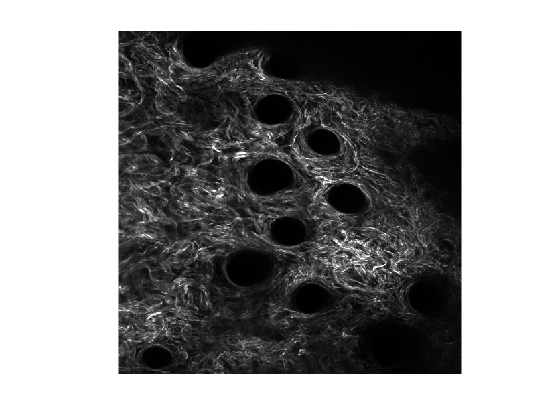

clear, clc, close all

shgim = imread('.\examples\shg-image\shg-intensity-image.tiff');

% Display the middle slice
figure; 
imagesc(shgim);
colormap gray;
axis image;
axis off;

Now we can load the trained convolutional neural network. Please note that this requires the `importONNXLayers` function, which is a free add-on for MATLAB. Using this function in the following code chunk will produce a warning and generate a "+collagen-cnn" folder due to incompatibility with upsampling. The network will still function as expected once loaded.

% Load the network
net = dlnetwork(importONNXLayers('.\files\collagen-cnn.onnx',TargetNetwork="dlnetwork"));

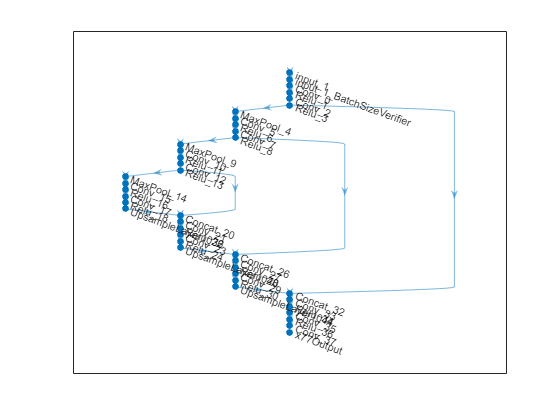


% Set up the sigmoid function
sigmoid = @(x) 1./(1+exp(-x));

% Plot the network architecture
figure;
plot(layerGraph(net));

Finally we can generate a forward pass for the intensity images

% Check for GPU availability 
gpu = canUseGPU;

tempImage = dlarray(single(shgim)./8191,'SSCB');

% Check for GPU availability
if gpu
    tempImage = gpuArray(tempImage);
end

% Forward pass
predMask = extractdata(forward(net,tempImage));

if gpu
    predMask = gather(predMask);
end

% Calculate a probability map using the sigmoid function
predMask = sigmoid(predMask);

% Finally, apply a threshold of 0.56 (see publication for explanation)
mask = (predMask > 0.56);


Visualize the masks and compare to the ground truth image

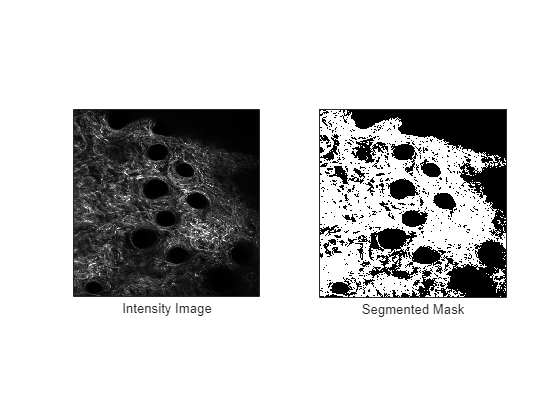

figure; 

subplot(1,2,1)
imagesc(shgim);
set(gca,'XTick',[]); set(gca,'YTick',[]);
colormap gray; axis image;
xlabel('Intensity Image')

subplot(1,2,2)
imagesc(mask);
set(gca,'XTick',[]); set(gca,'YTick',[]);
colormap gray; axis image;
xlabel('Segmented Mask')